% SLIM Design Using a Matlab Program
clear all;
clc;

## Variable names changed (for consistency with thesis paper)

'Vcrated' changed to 'Vr' - Rated rotor velocity (m/s) 'pw' changed to 'Np' - No. of parallel wires 'wire_d' changed to 'Dw' - Diameter of selected copper wire (mm)

## Assign Design parameters

designno = 69;   % Set Design Case no.

switch designno
    
    case 0 % Keith's Design Parameters - case no. 0
        
        % ElectroMagnetic constants
        mu0 = 4*pi*10^-7    % Permeability of free-space    **GOOD**
        mu = 4000*mu0       % Magnetic Permeability of laminated steel    **GOOD**
%         mu = 8*10^-4        % Magnetic Permeability for carbon steel    **GOOD**
        rhow = 19.27*10^-9  % Copper volume resistivity
        rhor = 28.85*10^-9  % Capsule conductor volume resistivity
        btmax = 1.6         % Maximum allowable flux density in tooth (T)
        bymax = 1.3         % Maximum allowable flux density in yoke (T)
        J1 = 6*10^6         % Stator current density (A/m^2)
        
        % Design parameters
        d = 0.0105          % Rotor outer thickness (m)
        m = 3               % Number of phases	**GOOD**
        Vline = 75          % RMS line-to-line voltage (V)
        f = 250             % Supply frequency (Hz)
%         f = 62             % Supply frequency (Hz)
        p = 6               % Number of poles
        q1 = 2              % Number of slots per pole per phase	**GOOD**
        Ws = 0.038          % Width of the stator (m)	**GOOD**
        gm = 0.004          % Physical air gap (m)
        
        Srated = 0.10       % Rated slip
        Fsprime = 800       % Target thrust (N)
        Vr = 120            % Rated rotor velocity (m/s)
%         Vr = 30            % Rated rotor velocity (m/s)
        
	case 1 % Keith's Design Parameters - case no. 1
        
        % ElectroMagnetic constants
        mu0 = 4*pi*10^-7    % Permeability of free-space    **GOOD**
        mu = 4000*mu0       % Magnetic Permeability of laminated steel    **GOOD**
%         mu = 8*10^-4        % Magnetic Permeability for carbon steel    **GOOD**
        rhow = 19.27*10^-9  % Copper volume resistivity
        rhor = 28.85*10^-9  % Capsule conductor volume resistivity
        btmax = 1.6         % Maximum allowable flux density in tooth (T)
        bymax = 1.3         % Maximum allowable flux density in yoke (T)
        J1 = 6*10^6         % Stator current density (A/m^2)
        
        % Design parameters
        d = 0.0105          % Rotor outer thickness (m)
        m = 3               % Number of phases	**GOOD**
        Vline = 75          % RMS line-to-line voltage (V)
        f = 250              % Supply frequency (Hz)
        p = 4               % Number of poles
        q1 = 2              % Number of slots per pole per phase	**GOOD**
        Ws = 0.038          % Width of the stator (m)	**GOOD**
        gm = 0.004           % Physical air gap (m)
        
        Srated = 0.10       % Rated slip
        Fsprime = 800       % Target thrust (N)
        Vr = 120            % Rated rotor velocity (m/s)
        
		
	case 2 % Keith's Design Parameters - case no. 2
        
        % ElectroMagnetic constants
        mu0 = 4*pi*10^-7    % Permeability of free-space    **GOOD**
        mu = 4000*mu0       % Magnetic Permeability of laminated steel    **GOOD**
%         mu = 8*10^-4        % Magnetic Permeability for carbon steel    **GOOD**
        rhow = 19.27*10^-9  % Copper volume resistivity
        rhor = 28.85*10^-9  % Capsule conductor volume resistivity
        btmax = 1.6         % Maximum allowable flux density in tooth (T)
        bymax = 1.3         % Maximum allowable flux density in yoke (T)
        J1 = 6*10^6         % Stator current density (A/m^2)
        
        % Design parameters
        d = 0.0105          % Rotor outer thickness (m)
        m = 3               % Number of phases	**GOOD**
        Vline = 75          % RMS line-to-line voltage (V)
        f = 250             % Supply frequency (Hz)
        p = 2               % Number of poles
        q1 = 2              % Number of slots per pole per phase	**GOOD**
        Ws = 0.038          % Width of the stator (m)	**GOOD**
        gm = 0.004          % Physical air gap (m)
        
        Srated = 0.10       % Rated slip
        Fsprime = 800       % Target thrust (N)
        Vr = 120            % Rated rotor velocity (m/s)
        
	case 3 % Keith's Design Parameters - case no. 3
        
        % ElectroMagnetic constants
        mu0 = 4*pi*10^-7    % Permeability of free-space    **GOOD**
        mu = 4000*mu0       % Magnetic Permeability of laminated steel    **GOOD**
%         mu = 8*10^-4        % Magnetic Permeability for carbon steel    **GOOD**
        rhow = 19.27*10^-9  % Copper volume resistivity
        rhor = 28.85*10^-9  % Capsule conductor volume resistivity
        btmax = 1.6         % Maximum allowable flux density in tooth (T)
        bymax = 1.3         % Maximum allowable flux density in yoke (T)
        J1 = 6*10^6         % Stator current density (A/m^2)
        
        % Design parameters
        d = 0.021           % Rotor outer thickness (m)
        m = 3               % Number of phases	**GOOD**
        Vline = 75          % RMS line-to-line voltage (V)
        f = 250             % Supply frequency (Hz)
        p = 2               % Number of poles
        q1 = 2              % Number of slots per pole per phase	**GOOD**
        Ws = 0.038          % Width of the stator (m)	**GOOD**
        gm = 0.004          % Physical air gap (m)
        
        Srated = 0.10       % Rated slip
        Fsprime = 800       % Target thrust (N)
        Vr = 120            % Rated rotor velocity (m/s)
        
	case 4 % Keith's Design Parameters - case no. 4 for a puller on the track with wheels for air-gap spacing
        
        % ElectroMagnetic constants
        mu0 = 4*pi*10^-7    % Permeability of free-space    **GOOD**
        rhow = 19.27*10^-9  % Copper volume resistivity
        rhor = 28.85*10^-9  % Capsule conductor volume resistivity
        btmax = 1.6         % Maximum allowable flux density in tooth (T)
        bymax = 1.3         % Maximum allowable flux density in yoke (T)
        J1 = 6*10^6         % Stator current density (A/m^2)
        
        % Design parameters
        d = 0.0105          % Rotor outer thickness (m)
        m = 3               % Number of phases    **GOOD**
        Vline = 150         % RMS line-to-line voltage (V)
        f = 60              % Supply frequency (Hz)
        p = 4               % Number of poles
        q1 = 2              % Number of slots per pole per phase    **GOOD**
        Ws = 0.051          % Width of the stator (m)    **GOOD**
        gm = 0.001          % Physical air gap (m)
        
        Srated = 0.10       % Rated slip
        Fsprime = 1600       % Target thrust (N)
        Vr = 120            % Rated rotor velocity (m/s)
        
	case 5 % Keith's Design Parameters - case no. 4 for a puller on the track with wheels for air-gap spacing
        
        % ElectroMagnetic constants
        mu0 = 4*pi*10^-7    % Permeability of free-space    **GOOD**
        rhow = 19.27*10^-9  % Copper volume resistivity
        rhor = 28.85*10^-9  % Capsule conductor volume resistivity
        btmax = 1.6         % Maximum allowable flux density in tooth (T)
        bymax = 1.3         % Maximum allowable flux density in yoke (T)
        J1 = 6*10^6         % Stator current density (A/m^2)
        
        % Design parameters
        d = 0.0105          % Rotor outer thickness (m)
        m = 3               % Number of phases    **GOOD**
        Vline = 150         % RMS line-to-line voltage (V)
        f = 60              % Supply frequency (Hz)
        p = 4               % Number of poles
        q1 = 2              % Number of slots per pole per phase    **GOOD**
        Ws = 0.051          % Width of the stator (m)    **GOOD**
        gm = 0.001          % Physical air gap (m)
        
        Srated = 0.05       % Rated slip
        Fsprime = 1600       % Target thrust (N)
        Vr = 120            % Rated rotor velocity (m/s)
        
    case 42 % Table 4-2 Design Parameters
        
        % ElectroMagnetic constants
        mu0 = 4*pi*10^-7    % Permeability of free-space    **GOOD**
        mu = 4000*mu0       % Magnetic Permeability of laminated steel    **GOOD**
%         mu = 8*10^-4        % Magnetic Permeability for carbon steel    **GOOD**
        rhow = 19.27*10^-9  % Copper volume resistivity
        rhor = 28.85*10^-9  % Capsule conductor volume resistivity
        btmax = 1.6         % Maximum allowable flux density in tooth (T)
        bymax = 1.3         % Maximum allowable flux density in yoke (T)
        J1 = 6*10^6         % Stator current density (A/m^2)
        
        % Design parameters
        d = 0.003           % Aluminum Rotor outer thickness (m)
        m = 3               % Number of phases	**GOOD**
        Vline = 480         % RMS line-to-line voltage (V)
        f = 60              % Supply frequency (Hz)
        p = 4               % Number of poles
        q1 = 1              % Number of slots per pole per phase	**GOOD**
        Ws = 3.14           % Width of the stator (m)	**GOOD**
        gm = 0.01           % Physical air gap (m)
        
        Srated = 0.10       % Rated slip
%         Srated = 0.05       % Rated slip
        Fsprime = 8161      % Target thrust (N)
%         Fsprime = 8177      % Target thrust (N)
        Vr = 15.5           % Rated rotor velocity (m/s)
        
    case 44 % Table 4-4 Design Parameters
        
        % ElectroMagnetic constants
        mu0 = 4*pi*10^-7    % Permeability of free-space    **GOOD**
        mu = 4000*mu0       % Magnetic Permeability of laminated steel    **GOOD**
%         mu = 8*10^-4        % Magnetic Permeability for carbon steel    **GOOD**
        rhow = 19.27*10^-9  % Copper volume resistivity
        rhor = 28.85*10^-9  % Capsule conductor volume resistivity
        btmax = 1.6         % Maximum allowable flux density in tooth (T)
        bymax = 1.3         % Maximum allowable flux density in yoke (T)
        J1 = 6*10^6         % Stator current density (A/m^2)
        
        % Design parameters
        d = 0.003           % Aluminum Rotor outer thickness (m)
        m = 3               % Number of phases	**GOOD**
        Vline = 480         % RMS line-to-line voltage (V)
        f = 60              % Supply frequency (Hz)
        p = 4               % Number of poles
        q1 = 1              % Number of slots per pole per phase	**GOOD**
        Ws = 3.1416         % Width of the stator (m)	**GOOD**
        gm = 0.01           % Physical air gap (m)
        
        Srated = 0.10       % Rated slip
        Fsprime = 8161      % Target thrust (N)
        Vr = 15.5           % Rated rotor velocity (m/s) 
        
    case 45 % Table 4-5 Design Parameters
        
        % ElectroMagnetic constants
        mu0 = 4*pi*10^-7    % Permeability of free-space    **GOOD**
        mu = 4000*mu0       % Magnetic Permeability of laminated steel    **GOOD**
%         mu = 8*10^-4        % Magnetic Permeability for carbon steel    **GOOD**
        rhow = 19.27*10^-9  % Copper volume resistivity
        rhor = 28.85*10^-9  % Capsule conductor volume resistivity
        btmax = 1.6         % Maximum allowable flux density in tooth (T)
        bymax = 1.3         % Maximum allowable flux density in yoke (T)
        J1 = 6*10^6         % Stator current density (A/m^2)
        
        % Design parameters
        d = 0.003           % Aluminum Rotor outer thickness (m)
        m = 3               % Number of phases	**GOOD**
        Vline = 480         % RMS line-to-line voltage (V)
        f = 60              % Supply frequency (Hz)
        p = 4               % Number of poles
        q1 = 1              % Number of slots per pole per phase	**GOOD**
        Ws = 3.1416         % Width of the stator (m)	**GOOD**
        gm = 0.01           % Physical air gap (m)
        
        Srated = 0.10       % Rated slip
        Fsprime = 8171      % Target thrust (N)
        Vr = 15.5           % Rated rotor velocity (m/s) 
        
    case 54 % Table 5-4 Design Parameters
        
        % ElectroMagnetic constants
        mu0 = 4*pi*10^-7    % Permeability of free-space    **GOOD**
        mu = 4000*mu0       % Magnetic Permeability of laminated steel    **GOOD**
%         mu = 8*10^-4        % Magnetic Permeability for carbon steel    **GOOD**
        rhow = 19.27*10^-9  % Copper volume resistivity
        rhor = 28.85*10^-9  % Capsule conductor volume resistivity
        btmax = 1.6         % Maximum allowable flux density in tooth (T)
        bymax = 1.3         % Maximum allowable flux density in yoke (T)
        J1 = 6*10^6         % Stator current density (A/m^2)
        
        % Design parameters
        d = 0.003           % Aluminum Rotor outer thickness (m)
        m = 3               % Number of phases	**GOOD**
        Vline = 480         % RMS line-to-line voltage (V)
        f = 60              % Supply frequency (Hz)
        p = 4               % Number of poles
        q1 = 1              % Number of slots per pole per phase	**GOOD**
        Ws = 3.1416         % Width of the stator (m)	**GOOD**
        gm = 0.01           % Physical air gap (m)
        
        Srated = 0.10       % Rated slip
        Fsprime = 8161      % Target thrust (N)
%         Srated = 0.05       % Rated slip
%         Fsprime = 8177      % Target thrust (N)
        Vr = 15.5           % Rated rotor velocity (m/s) 
        
case 69 % Table 5-4 Design Parameters
        
        % ElectroMagnetic constants
        mu0 = 4*pi*10^-7    % Permeability of free-space    **GOOD**
        mu = 4000*mu0       % Magnetic Permeability of laminated steel    **GOOD**
%         mu = 8*10^-4        % Magnetic Permeability for carbon steel    **GOOD**
        rhow = 19.27*10^-9  % Copper volume resistivity
        rhor = 28.85*10^-9  % Capsule conductor volume resistivity
        btmax = 1.6         % Maximum allowable flux density in tooth (T)
        bymax = 1.3         % Maximum allowable flux density in yoke (T)
        J1 = 6*10^6         % Stator current density (A/m^2)
        
        % Design parameters
        d = 0.003           % Aluminum Rotor outer thickness (m)
        m = 3               % Number of phases	**GOOD**
        Vline = 480         % RMS line-to-line voltage (V)
        f = 40              % Supply frequency (Hz)
        p = 1               % Number of poles
        q1 = 3              % Number of slots per pole per phase	**GOOD**
        Ws = 3.1416         % Width of the stator (m)	**GOOD**
        gm = 0.01           % Physical air gap (m)
        
        Srated = 0.10       % Rated slip
        Fsprime = 4000      % Target thrust (N)
%         Srated = 0.05       % Rated slip
%         Fsprime = 8177      % Target thrust (N)
        Vr =  180         % Rated rotor velocity (m/s) 
        
end

mu0 = 1.2566e-06

mu = 0.0050

rhow = 1.9270e-08

rhor = 2.8850e-08

btmax = 1.6000

bymax = 1.3000

J1 = 6000000

d = 0.0030

m = 3

Vline = 480

f = 40

p = 1

q1 = 3

Ws = 3.1416

gm = 0.0100

Srated = 0.1000

Fsprime = 4000

Vr = 180

## Optimize for design case and calculate output performance

% Data from the PCP design procedure
V1 = Vline/sqrt(3);         % Rated primary RMS - Eqn 4.16
Vs = Vr/(1 - Srated);       % Sychronous velocity (m/s)	**GOOD**
tau = Vs/(2*f);             % Pole pitch	**GOOD**
lambda = tau/(m*q1);        % Slot pitch    **GOOD**
Ls = p*tau;                 % Stator Length	**GOOD**

for i = 1:30
    
    N1 = p*q1*i;
    ncos0 = 0.2;
    ncos1(i) = 1;
    
    while abs(ncos0 - ncos1(i)) > 0.0001

        I1prime = (Fsprime*Vr)/(m*V1*ncos0);
        Aw = I1prime/J1;
        As = (10*i*Aw)/7;
        ws = lambda/2;
        wt = ws;
        hs = As/ws;
        go = gm + d;
        gamma = (4/pi)*(((ws/(2*go))*atan(ws/(2*go))) - log(sqrt(1 + ((ws/(2*go))^2))));
        kc = lambda/(lambda - gamma*go);
        ge = kc*go;
        kw = sin(pi/(2*m))/(q1*sin(pi/(2*m*q1)));
        G = 2*mu0*f*tau^2/(pi*(rhor/d)*ge);     % Goodness factor for in vacuum
%         G = 2*mu*f*tau^2/(pi*(rhor/d)*ge);     % Goodness factor
        a = pi/2;
        ae = a + ge/2;
        Lce = tau;
        beta1 = 1;
        lamda_s = (hs*(1+3*beta1))/(12*ws);
        lamda_e = (0.3*(3*beta1-1)); 
        lamda_d = 5*(ge/ws)/(5 + 4*(go/ws));

        %Equivalent Circuit Components
        R1(i) = rhow*(4*a + 2*Lce)*J1*N1/I1prime;
        a1(i) = lamda_s*(1 + 3/p) + lamda_d;
        b1(i) = lamda_e*Lce;
        X1(i) = 8*mu0*pi*f*((a1(i)*2*a/q1) + b1(i))*N1^2/p; % Leakage Reactance
        Xm(i) = (48*mu0*pi*f*ae*kw*N1^2*tau)/(pi^2*p*ge);  % Magnetizing Reactance
        R2(i) = Xm(i)/G;

        Z(i) = R1(i) + j*X1(i) + ((j*R2(i)*Xm(i))/Srated)/((R2(i)/Srated) + j*Xm(i));

        I1(i) = V1/abs(Z(i));
        I2(i) = j*I1(i)*Xm(i)/(R2(i)/Srated + j*Xm(i));
        Im(i) = I1(i) - I2(i);

        %Actual TLIM Thrust
        Fs(i) = (m*abs(I1(i))^2*R2(i))/(((1/(Srated*G)^2) + 1)*Vs*Srated)   % Eqn 3.51
        diff(i) = Fs(i) - Fsprime;
        dmin = min(abs(diff));
        Pout = Fs*Vr;   % Eqn 3.4
        Pin = Pout + m*abs(I2(i))^2*R2(i) + m*abs(I1(i))^2*R1(i);   % Eqn 3.52
        eta = Pout/Pin;
        PF = cos(angle(Z(i)));
        ncos1(i) = eta*PF;
        ncos0 = (ncos0+ncos1(i))/2;
    end
end

Fs = 2.5636e+04

Fs = 2.5465e+04

Fs = 2.5218e+04

Fs = 2.5081e+04

Fs = 2.5013e+04

Fs = 2.4979e+04

Fs = 2.4963e+04

Fs = 2.4955e+04

Fs = 2.4952e+04

Fs = 2.4950e+04

Fs = 2.4949e+04

Fs = 	1.0e+04 *

    2.4949    0.6170


Fs = 	1.0e+04 *

    2.4949    0.6394


Fs = 	1.0e+04 *

    2.4949    0.6416


Fs = 	1.0e+04 *

    2.4949    0.6415


Fs = 	1.0e+04 *

    2.4949    0.6412


Fs = 	1.0e+04 *

    2.4949    0.6410


Fs = 	1.0e+04 *

    2.4949    0.6409


Fs = 	1.0e+04 *

    2.4949    0.6408


Fs = 	1.0e+04 *

    2.4949    0.6408


Fs = 	1.0e+04 *

    2.4949    0.6408


Fs = 	1.0e+04 *

    2.4949    0.6407


Fs = 	1.0e+04 *

    2.4949    0.6407


Fs = 	1.0e+04 *

    2.4949    0.6407


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2603


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2782


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2821


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2834


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2839


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2841


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2842


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1386


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1520


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1555


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1568


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1574


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1577


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1578


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1579


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1579


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1579


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1580


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1580


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1580


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1580    0.0839


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1580    0.0941


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1580    0.0971


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1580    0.0983


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1580    0.0988


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1580    0.0991


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1580    0.0992


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1580    0.0993


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1580    0.0993


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1580    0.0993


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1580    0.0994


Fs = 	1.0e+04 *

    2.4949    0.6407    0.2843    0.1580    0.0994


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0552


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0630


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0656


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0666


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0671


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0674


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0675


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0384


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0446


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0468


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0477


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0481


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0484


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0485


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0279


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0329


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0347


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0355


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0359


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0361


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0363


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0363


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0363


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0209


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0250


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0266


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0273


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0277


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0278


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0279


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0280


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0280


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0161


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0194


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0208


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0215


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0218


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0220


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0221


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0221


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0221


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0126


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0154


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0166


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0172


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0175


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0177


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0178


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0178


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0178


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0178


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0101


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0124


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0135


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0140


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0143


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0144


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0145


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0082


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0101


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0111


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0116


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0118


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0119


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0120


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0067


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0084


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0092


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0096


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0099


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0100


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0101


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0101


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0101


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0056


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0070


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0077


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0081


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0083


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0084


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0085


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0047


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0059


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0065


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0069


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0071


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0072


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0073


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0073


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0073


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0073


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0073


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0040


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0050


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0056


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0059


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0061


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0062


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0062


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0034


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0043


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0048


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0051


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0052


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0053


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0054


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0054


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0054


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0029


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0037


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0041


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0044


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0045


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0046


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0047


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0047


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0047


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0047


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0025


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0032


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0036


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0038


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0039


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0040


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0041


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0041


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0041


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0041


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0022


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0027


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0031


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0033


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0034


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0035


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0036


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0036


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0036


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0036


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0036


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0019


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0024


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0027


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0029


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0030


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0031


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0031


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0017


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0021


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0024


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0025


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0027


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0027


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0028


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0028


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0028


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0028


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0028


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0028


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0015


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0018


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0021


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0022


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0023


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0024


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0013


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0016


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0018


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0020


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0021


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0021


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0022


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0022


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0022


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0022


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0022


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0022


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0022


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0012


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0014


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0016


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0018


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0018


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0019


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0019


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0011


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0013


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0014


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0016


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0016


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0017


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0017


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0017


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0009


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0011


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0013


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0014


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0015


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0015


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0015


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0008


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0010


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0011


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0012


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0013


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0013


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014    0.0008


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014    0.0009


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014    0.0010


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014    0.0011


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014    0.0012


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014    0.0012


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014    0.0012


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014    0.0013


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014    0.0013


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014    0.0013


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014    0.0013


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014    0.0013


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014    0.0013


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014    0.0013


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014    0.0013


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014    0.0013


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014    0.0013


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014    0.0013


Fs =     2.4949    0.6407    0.2843    0.1580    0.0994    0.0676    0.0486    0.0364    0.0281    0.0222    0.0179    0.0146    0.0121    0.0102    0.0086    0.0074    0.0063    0.0055    0.0048    0.0042    0.0037    0.0032    0.0029    0.0025    0.0023    0.0020    0.0018    0.0016    0.0014    0.0013



k = 1; 
while dmin~=abs(diff(k))
    k = k + 1;
end

Nc = k;         % Number of turns per slot
N1 = p*q1*Nc;   % Number of turns per phase
Fs = Fs(k);     % Estimated thrust based on Nc (N)
I1 = I1(k);     % Actual rated stator RMS current (A)

ncos1 = ncos1(k);

A = [   3	5.8;
        4	5.189;
        5	4.62;
        6	4.1148;
        7	3.665;
        8	3.2639;
        9   2.9057;
        10	2.588   ];

gauge = 0;

while (gauge < 8)
    
    gauge = gauge + 1;
%     gauge = 5
    Np = 0;
%     r = 0;    % Unused variable
    wt = 1;
    wtmin = 0;
%     g = 0;    % Unused variable
%     r = 0;    % redundant
    
    while (wt - wtmin) > 0.0152
        
%         r = r + 1;    % Unused variable
%         g = g + 1;    % Unused variable
        Dw = A(gauge,2);	% Diameter of selected copper wire (mm)
        Np = Np + 1;
        ws = (Dw*10^-3*Np) + 2.2*10^-3;	% Eqn 4.18
        wt = lambda - ws;	% Eqn 4.19
        Aw = Np*pi/4*Dw^2*1e-6;
        As = (10*Nc*Aw)/7;
        hs = As/ws;
        gm = 0.01;
        go = gm + d;
        gamma = (4/pi)*(((ws/(2*go))*atan(ws/(2*go))) - log(sqrt(1 + ((ws/(2*go))^2))));
        kc = lambda/(lambda - gamma*go);
        ge = kc*go;
        G = 2*mu0*f*tau^2/(pi*(rhor/d)*ge);     % Goodness factor for in vacuum
%         G = 2*mu*f*tau^2/(pi*(rhor/d)*ge);     % Goodness factor
        kw = sin(pi/(2*m))/(q1*sin(pi/(2*m*q1)));
        a = pi/2;
        ae = a + ge/2;
        Lce = tau;
        beta1 = 1;
        lamda_s = (hs*(1 + 3*beta1))/(12*ws);
        lamda_e = (0.3*(3*beta1 - 1));
        lamda_d = 5*(ge/ws)/(5 + 4*(go/ws));

        % Equivalent Circuit Components
        R1 = rhow*(4*a + 2*Lce)*J1*N1/I1prime;
        a1 = lamda_s*(1 + 3/p)+lamda_d;
        b1 = lamda_e*Lce;
        X1 = 8*mu0*pi*f*((a1*2*a/q1) + b1)*N1^2/p; % Leakage Reactance
        Xm = (48*mu0*pi*f*ae*kw*N1^2*tau)/(pi^2*p*ge);  % Magnetizing Reactance
        R2 = Xm/G;
        Z = R1 + j*X1 + (R2/Srated*j*Xm)/(R2/Srated + j*Xm);
        I1 = V1/abs(Z);
        I2 = j*I1*Xm/(R2/Srated + j*Xm);
        Im = I1-I2;
        wtmin = 2*sqrt(2)*m*kw*N1*abs(Im)*mu0*lambda/(pi*p*ge*btmax);
        
    end
    
    hy = 4*sqrt(2)*m*kw*N1*abs(Im)*mu0*Ls/(pi*pi*p*p*ge*bymax);  % Yoke height of stator core
%     hy = 4*sqrt(2)*m*kw*N1*abs(Im)*mu*Ls/(pi*pi*p*p*ge*bymax);  % Yoke height of stator core
    para_wires(gauge) = Np;
    slot_width(gauge) = ws; 
    tooth_width(gauge) = wt;
    min_toothwidth(gauge) = wtmin;
    height_slot(gauge) = hs;
    Area_wire(gauge) = Aw;
    Area_slot(gauge) = As;
    Num_c(gauge) = Nc;
    Num_1(gauge) = N1;
    Sta_I(gauge) = I1;
    gap_e(gauge) = ge;
    current_den(gauge) = abs(I1)/Aw;
    height_yoke(gauge) = 4*sqrt(2)*m*kw*N1*(Im)*mu0*Ls/(pi*pi*p*p*ge*bymax);
%     height_yoke(gauge) = 4*sqrt(2)*m*kw*N1*(Im)*mu*Ls/(pi*pi*p*p*ge*bymax);
    final_thrust(gauge) = (m*abs(I1)^2*R2)/(((1/(Srated*G)^2) + 1)*Vs*Srated);
    output(gauge) = final_thrust(gauge)*Vr;
    input(gauge) = output(gauge) + m*abs(I2)^2*R2 + m*abs(I1)^2*R1;
    efficiency(gauge) = output(gauge)/input(gauge);
    difference(gauge) = final_thrust(gauge) - Fsprime;
    diffmin(gauge) = min(abs(difference));
    
end

kk = min(diffmin);
jj = 1;

while kk ~= abs(diffmin(jj))
    
    jj = jj + 1;
    
end

best_wiregauge = A(jj,1)

best_wiregauge = 10


%$$$ To Generate the Characteristic curves $$$

% vel_sta = 17.22;    % Only applies for Vr = 15.5 & Srated = 10%
% slip = 0.1;         % Only applies for Srated = 10%
vel_sta = Vs;
% slip = Srated;    % commented out, b/c variable gets overwritten anyway
e = 1;

for slip = 0.000001:0.01:1
    
    vel_rot(e) = vel_sta*(1 - slip);
    if abs(Vr - vel_rot(e))/Vr < 0.01
        n_Vr = e;   % Index for where v = Vr
    end
    impz(e) = R1 + j*X1 + (R2/slip*j*Xm)/(R2/slip + j*Xm);
    i1(e) = V1/abs(impz(e));
    i2(e) = j*i1(e)*Xm/(R2/slip + j*Xm);
    im(e) = i1(e) - i2(e);
    Force(e) = (m*(abs(i1(e)))^2*R2)/(((1/(slip*G)^2) + 1)*vel_sta*slip);
    out_pow(e) = Force(e)*vel_rot(e);
    in_pow(e) = out_pow(e) + m*abs(i2(e))^2*R2 + m*abs(i1(e))^2*R1;
    eff(e) = out_pow(e)/in_pow(e);
    e = e + 1;
    
end

## Miscellaneous calcs (not included in original code)

Physical properties

rhoiron = 7870;                     % Density of iron (kg/m^3)
rhocopper = 8960;                   % Density of copper (kg/m^3)

% Assumptions & Dummy values
lce = 0.1144;                       % Length of end connection

% Ammount of material required for construction of one SLIM stator
lw = 2*(Ws + lce)*N1;               % Length of one turn of copper winding inside a stator slot
Tlw = m*Np*lw;                      % Length of copper wire required for stator windings

Vyoke = Ls*Ws*hy;                   % Volume of iron required for stator yoke
Vtooth = Ws*wt*hs;                  % Volume of iron required for stator tooth
Vteeth = m*p*q1*Ws*wt*hs;           % Volume of iron required for stator teeth
Viron = Ws*(Ls*hy + m*p*q1*wt*hs);  % Total volume of iron required
Vcopper = Tlw*pi*(Dw*10^-3/2)^2;	% Volume of copper used (m^3)

Wiron = rhoiron*Viron;              % Total weight of iron required
Wcopper = rhocopper*Vcopper;        % Total weight of copper required
Wstator = Wiron + Wcopper;          % Total weight of stator

## Generate table of outputs

VariableNames = {   
                    'Rated Slip';
                    'Yoke density';
                    'Tooth density';
                    'Core Width';
                    'SLIM Synchronous velocity';
                    'Rotor velocity';
                    'No. of Poles';
                    'Pole pitch';
                    'Slot pitch';
                    'Stator length';
                    '"Target" Thrust';
                    'No. of turns per slot';
                    'No. of turns per phase';
                    'Copper wire size in winding';
                    'Diameter of selected copper wire (mm)';
                    'Parallel wires';
                    'Slot width';
                    'Tooth width';
                    'Minimum tooth width';
                    'Slot depth';
                    'Stator core yoke height';
                    'Actual thrust at specified Vr';
                    'Output power at specified Vr';
                    'Input power at specified Vr';
                    'Stator efficiency at specified Vr';
                    'Actual rated stator RMS current';
                    'Actual stator current density';
                    'Total length of copper wire';
                    'Total weight of copper wire';
                    'Iron core weight';
                    'Total weight of one stator unit';
                };

Variable = {   
            'Srated';
            'bymax';
            'btmax';
            'Ws';
            'Vs';
            'Vr';
            'p';
            'tau';
            'lamda';
            'Ls';
            'Fsprime';
            'Nc';
            'N1';
            'gauge';
            'Dw';
            'Np';
            'ws';
            'wt';
            'wtmin';
            'hs';
            'hy';
            'Fs(Vr)';
            'Pout(Vr)';
            'Pin(Vr)';
            'eta(Vr)';
            'I1(Vr)';
            'J1';
            'Tlw';
            'Wcopper';
            'Wiron';
            'Wstator';
            };

Value = [    	Srated;
                bymax;
                btmax;
                Ws;
                Vs;
                Vr;
                p;
                tau;
                lambda;
                Ls;
                Fsprime;
                Nc;
                N1;
                gauge;
                Dw;
                Np;
                ws;
                wt;
                wtmin;
                hs;
                hy;
                Fs;
                out_pow(n_Vr);
                in_pow(n_Vr);
                eff(n_Vr);
                I1;
                abs(I1)/Aw; % Formula for current density
                Tlw;
                Wcopper;
                Wiron;
                Wstator
                ];

Units = {   
            '-';
            'Tesla';
            'Tesla';
            'm';
            'm/s';
            'm/s';
            '-';
            'm';
            'm';
            'm';
            'N';
            '-';
            '-';
            'AWG';
            'mm';
            '-';
            'm';
            'm';
            'm';
            'm';
            'm';
            'N';
            'W';
            'W';
            '-';
            'A';
            'A/m^2';
            'm';
            'kg';
            'kg';
            'kg';
            };

Dependencies = {   
            'Design Parameter/Constant';
            'Design Parameter/Constant';
            'Design Parameter/Constant';
            'Design Parameter/Constant';
            'Vr,Srated';
            'Design Parameter/Constant';
            'Design Parameter/Constant';
            'Vs,f';
            'tau,m,q1';
            'p,tau';
            'Design Parameter/Constant';
            'k';
            'p,q1,Nc';
            '(see loop counter)';
            'gauge';
            '(see loop counter)';
            'Dw,Np';
            'lambda,ws';
            'm,kw,N1,Im,mu0,lambda,p,ge,btmax';
            'Asws';
            'm,kw,N1,Im,mu0,Ls,pi,p,ge,bymax';
            'm,i1(e),R2,slip,G,vel_sta';
            'Force(e),vel_rot(e)';
            'out_pow(e),m,i2(e),R2,m,i1(e),R1';
            'out_pow(e),in_pow(e)';
            'V1,Z(i)';
            'Design Parameter/Constant';
            'm,Np,lw';
            'rhocopper,Vcopper';
            'rhoiron,Viron';
            'Wcopper,Wiron';
        };

line_reference = {   
            '';
            '';
            '';
            '';
            '146';
            '';
            '';
            '147';
            '148';
            '149';
            '';
            '211';
            '212';
            '231';
            '244';
            '231';
            '246';
            '247';
            '277';
            '164';
            '280';
            '327';
            '328';
            '329';
            '330';
            '189';
            '';
            '346';
            '352';
            '351';
            '353';
        };

size(Variable)

ans =     31     1


size(Value)

ans =     31     1


size(Units)

ans =     31     1


size(Dependencies)

ans =     31     1


size(line_reference)

ans =     31     1


size(VariableNames)

ans =     31     1



T = table(Variable,Value,Units,Dependencies,line_reference,'RowNames',VariableNames)

T = 31×5 table
                                              Variable       Value       Units              Dependencies             line_reference
                                             ___________    _______    _________    _____________________________    ______________

    Rated Slip                               {'Srated' }        0.1    {'-'    }    {'Design Parameter/Constant'}      {0×0 char}  
    Yoke density                             {'bymax'  }        1.3    {'Tesla'}    {'Design Parameter/Constant'}      {0×0 char}  
    Tooth density                            {'btmax'  }        1.6    {'Tesla'}    {'Design Parameter/Constant'}      {0×0 char}  
    Core Width                               {'Ws'     }     3.1416    {'m'    }    {'

## Write table to csv

formatSpec = 'SLIM_case_no_%0.f.csv';
filename = sprintf(formatSpec,designno);
writetable(T,filename)

## Graph Thrust and Efficiency

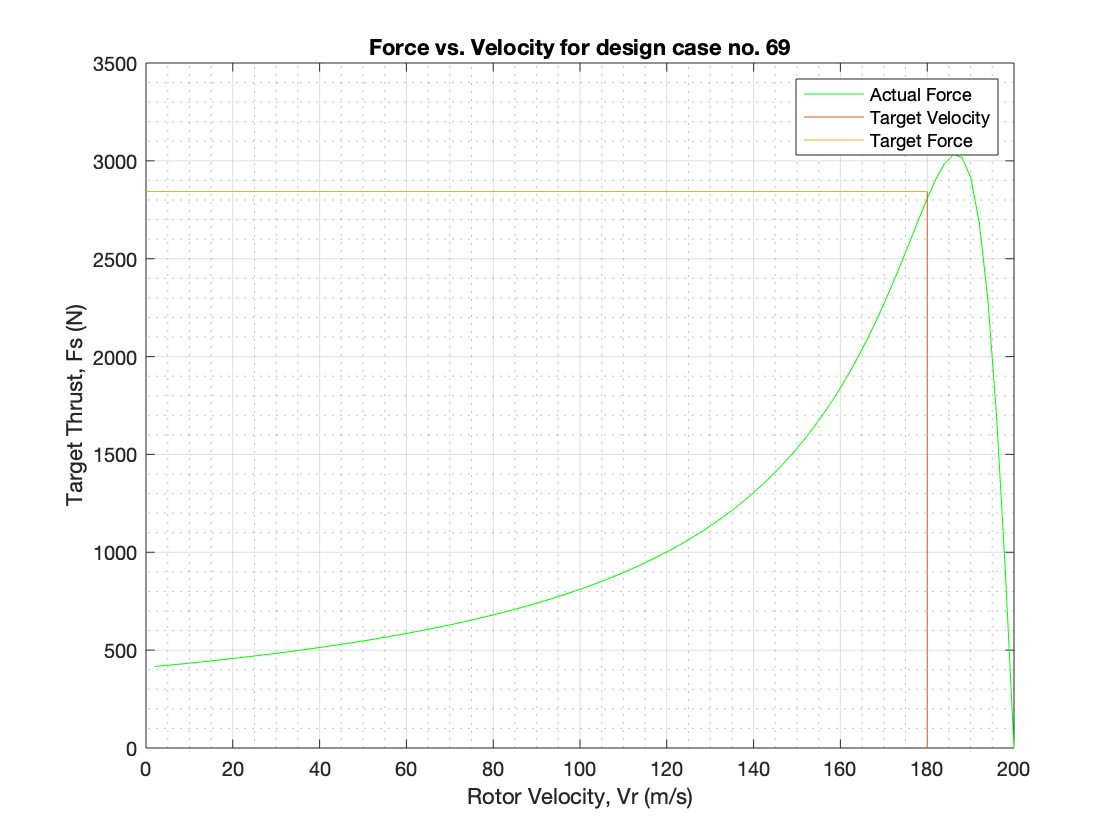

figure(1)
plot(vel_rot,Force,'green')
hold on
grid on
grid minor
ylabel('Target Thrust, Fs (N)')
xlabel('Rotor Velocity, Vr (m/s)')
% plot([15.5 15.5],[0,Fs])  % Only applies for Vr = 15.5
plot([Vr Vr],[0,Fs])
hold on;
% plot([0 15.5],[Fs Fs]);  % Only applies for Vr = 15.5
plot([0 Vr],[Fs Fs]);
hold on;
title(['Force vs. Velocity for design case no. ' num2str(designno)])
legend('Actual Force','Target Velocity','Target Force')

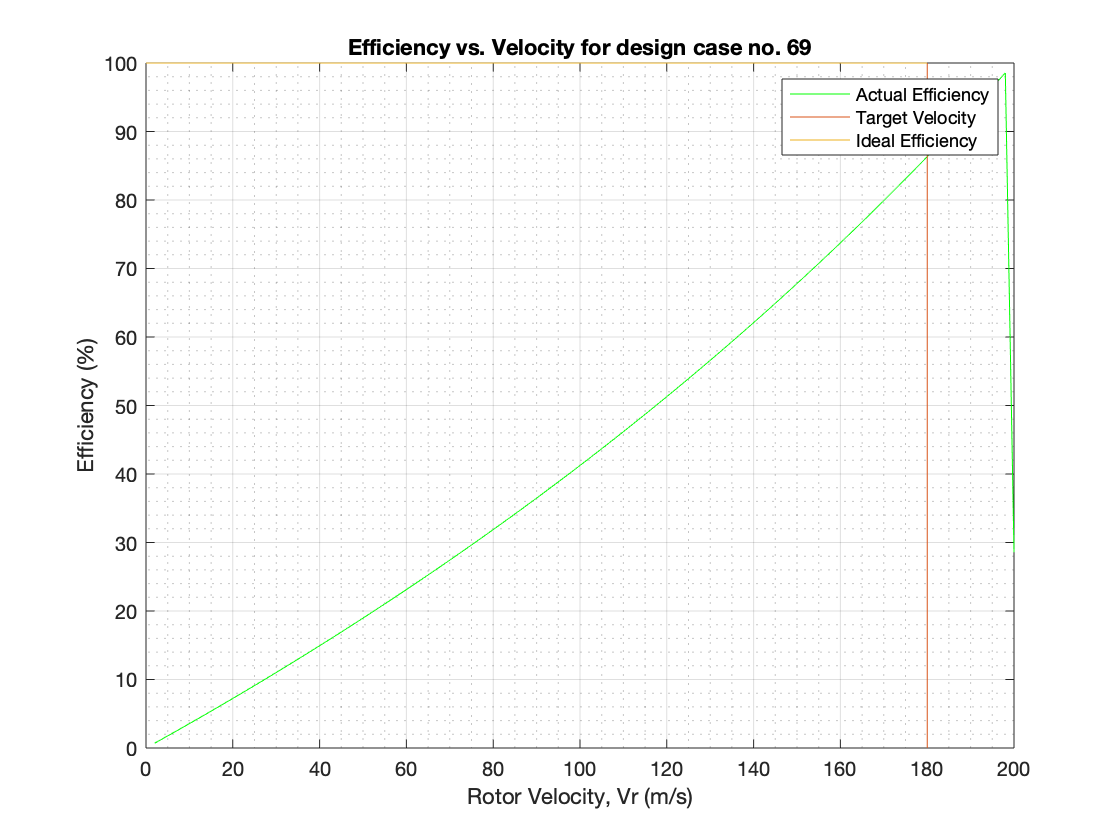


figure(2);
plot(vel_rot,eff*100,'green');
hold on;
% plot([15.5 15.5],[0 eta*100]);  % Only applies for Vr = 15.5
plot([Vr Vr],[0 eta*100]);
hold on;
% plot([0 Vr],[eta*100,eta*100]);  % Only applies for Vr = 15.5
plot([0 Vr],[eta*100,eta*100]);
hold on;
grid on
grid minor
ylabel('Efficiency (%)')
xlabel('Rotor Velocity, Vr (m/s)')
title(['Efficiency vs. Velocity for design case no. ' num2str(designno)])
legend('Actual Efficiency','Target Velocity','Ideal Efficiency')

## Assign Operating parameters

Reduced voltage and frequency with reduced rated rotor velocity run simulation at design parameters without relooping to find new values except calculate at the three changed constants

operatingno = 19;   % Set Design Case no.

switch operatingno
    
    case 10 % 
		factor = .001
		Vline = Vline * factor
		f = f * factor
		Vr = Vr * factor

	case 11 % 
		factor = .1
		Vline = Vline * factor
		f = f * factor
		Vr = Vr * factor
		
	case 12 %
		factor = .2
		Vline = Vline * factor
		f = f * factor
		Vr = Vr * factor
		
	case 13 %
		factor = .3
		Vline = Vline * factor
		f = f * factor
		Vr = Vr * factor
		
	case 14 %
		factor = .4
		Vline = Vline * factor
		f = f * factor
		Vr = Vr * factor
		
	case 19 %
		factor = .9
		Vline = Vline * factor
		f = f * factor
		Vr = Vr * factor
        
end

factor = 0.9000

Vline = 432

f = 36

Vr = 162

## Calculate output performance per design case and operating conditions

% Data from the PCP design procedure
V1 = Vline/sqrt(3);         % Rated primary RMS - Eqn 4.16
Vs = Vr/(1 - Srated);       % Sychronous velocity (m/s)	**GOOD**
tau = Vs/(2*f);             % Pole pitch	**GOOD**
lambda = tau/(m*q1);        % Slot pitch    **GOOD**
Ls = p*tau;                 % Stator Length	**GOOD**

Sta_I(gauge) = I1;
current_den(gauge) = abs(I1)/Aw;

vel_sta = Vs;
% slip = Srated;    % commented out, b/c variable gets overwritten anyway
e = 1;

for slip = 0.000001:0.01:1
    
    vel_rot(e) = vel_sta*(1 - slip);
    impz(e) = R1 + j*X1 + (R2/slip*j*Xm)/(R2/slip + j*Xm);
    i1(e) = V1/abs(impz(e));
    i2(e) = j*i1(e)*Xm/(R2/slip + j*Xm);
    im(e) = i1(e) - i2(e);
    Force(e) = (m*(abs(i1(e)))^2*R2)/(((1/(slip*G)^2) + 1)*vel_sta*slip);
    out_pow(e) = Force(e)*vel_rot(e);
    in_pow(e) = out_pow(e) + m*abs(i2(e))^2*R2 + m*abs(i1(e))^2*R1;
    eff(e) = out_pow(e)/in_pow(e);
    e = e + 1;
    
end

## Graph Thrust and Efficiency for operating conditions

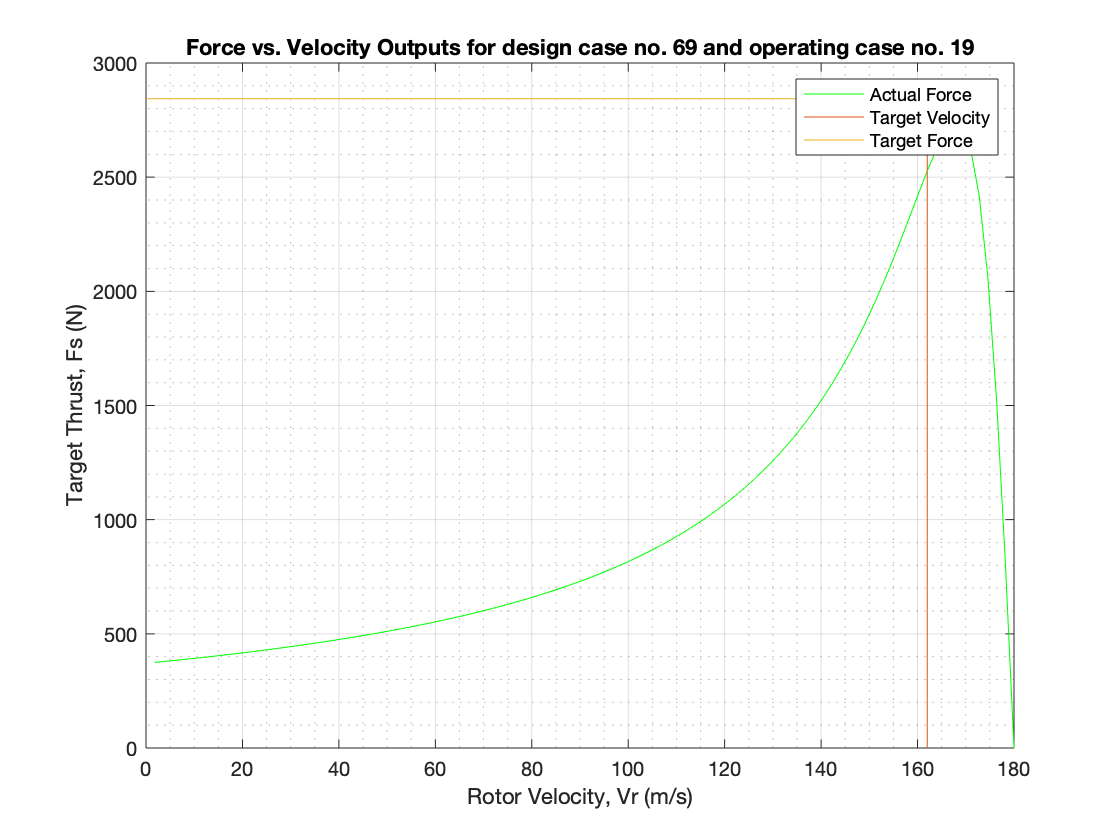

figure(3)
plot(vel_rot,Force,'green')
hold on
grid on
grid minor
ylabel('Target Thrust, Fs (N)')
xlabel('Rotor Velocity, Vr (m/s)')
% plot([15.5 15.5],[0,Fs])  % Only applies for Vr = 15.5
plot([Vr Vr],[0,Fs])
hold on;
% plot([0 15.5],[Fs Fs]);  % Only applies for Vr = 15.5
plot([0 Vr],[Fs Fs]);
hold on;
title(['Force vs. Velocity Outputs for design case no. ' num2str(designno) ' and operating case no. ',num2str(operatingno)])
legend('Actual Force','Target Velocity','Target Force')

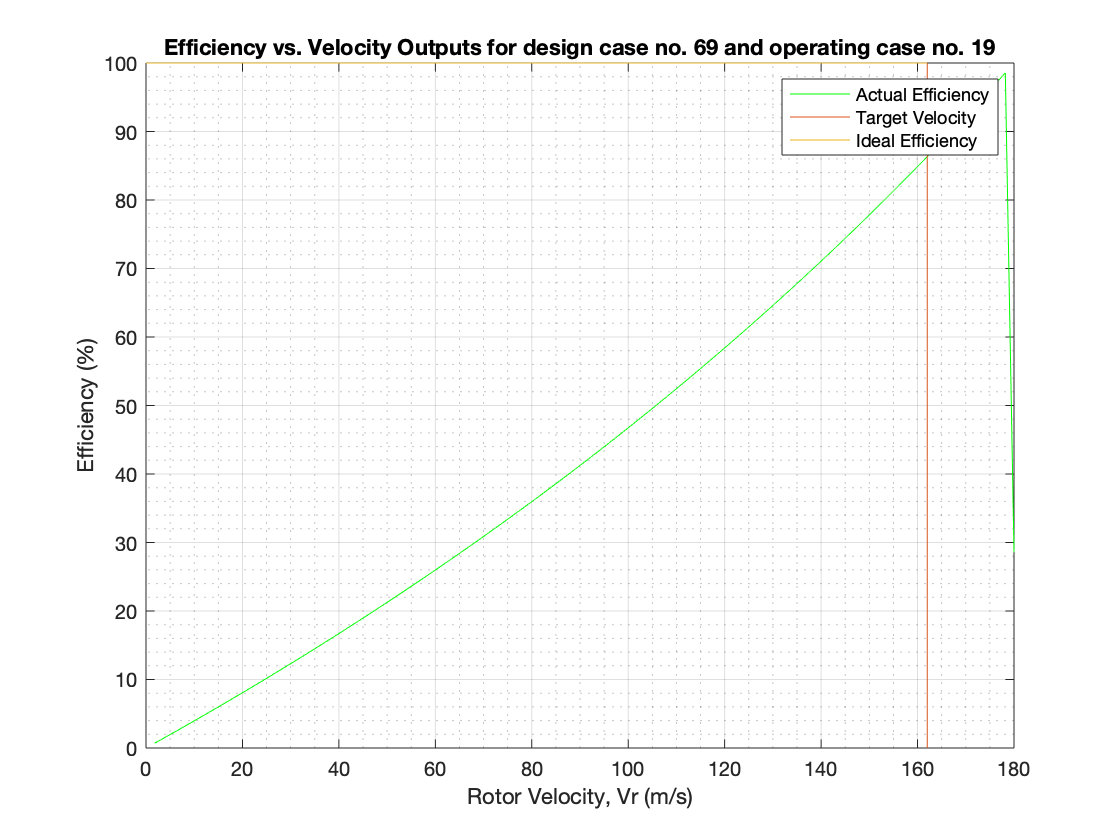


figure(4);
plot(vel_rot,eff*100,'green');
hold on;
% plot([15.5 15.5],[0 eta*100]);  % Only applies for Vr = 15.5
plot([Vr Vr],[0 eta*100]);
hold on;
% plot([0 Vr],[eta*100,eta*100]);  % Only applies for Vr = 15.5
plot([0 Vr],[eta*100,eta*100]);
hold on;
grid on
grid minor
ylabel('Efficiency (%)')
xlabel('Rotor Velocity, Vr (m/s)')
title(['Efficiency vs. Velocity Outputs for design case no. ' num2str(designno) ' and operating case no. ',num2str(operatingno)])
legend('Actual Efficiency','Target Velocity','Ideal Efficiency')